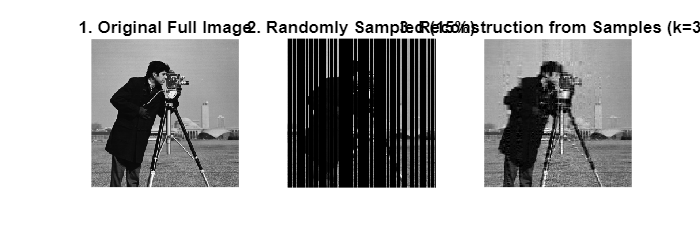

%% 1. Setup & Load Image
% We use the standard 'cameraman' image for demonstration
A = im2double(imread('cameraman.tif'));
[m, n] = size(A);

%% 2. Randomized Spatial Downsampling (Masking)
% We will keep only 15% of the spatial data (columns)
sampling_ratio = 0.15; 
k = round(n * sampling_ratio); 
p = 10; % Oversampling for stability

% Randomly select column indices (Spatial locations)
sample_idx = randperm(n, k + p);

% Create the downsampled matrix C (only the selected columns)
C = A(:, sample_idx);

%% 3. Reconstruction via Randomized Projection
% Find the basis Q for the sampled columns
[Q, ~] = qr(C, 0);

% Project the full (but theoretically "unknown") A onto Q
% In a real scenario, this B would be estimated from the samples
B = Q' * A;

% Reconstruct the image from the reduced spatial basis
A_reconstructed = Q * B;

%% 4. Visualization
figure('Position', [100, 100, 1200, 400]);

% Subplot 1: Original Image
subplot(1, 3, 1);
imshow(A);
title('1. Original Full Image');

% Subplot 2: Downsampled Representation
% We create a visualization of the 'gaps' in the data
A_masked = zeros(m, n);
A_masked(:, sample_idx) = A(:, sample_idx);
subplot(1, 3, 2);
imshow(A_masked);
title(['2. Randomly Sampled (' num2str(sampling_ratio*100) '%)']);

% Subplot 3: Reconstructed Image
subplot(1, 3, 3);
imshow(A_reconstructed);
title(['3. Reconstruction from Samples (k=' num2str(k) ')']);


% Calculate error
error_val = norm(A - A_reconstructed, 'fro') / norm(A, 'fro');
fprintf('Reconstruction Relative Error: %.4f\n', error_val);

Reconstruction Relative Error: 0.1222
